## cse327 hw3

Zian Shang

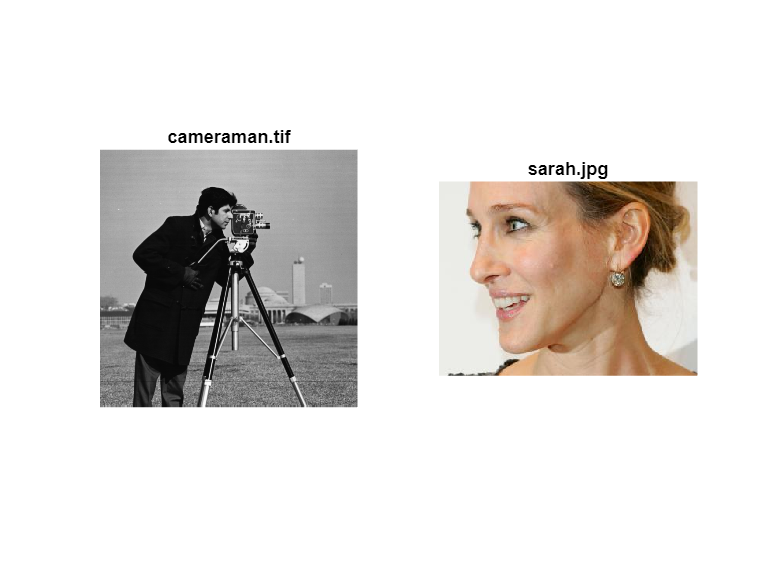

% read original images
[Icameraman, map1]=imread("cameraman.tif");
[Isarah, map2]=imread("sarah.jpg");

% convert both images to type double for calculation purpose
Icameraman=double(Icameraman);
Isarah=double(Isarah);

% display both images
figure
subplot(1, 2, 1), imshow(uint8(Icameraman)), title("cameraman.tif");
subplot(1, 2, 2), imshow(uint8(Isarah)), title("sarah.jpg");

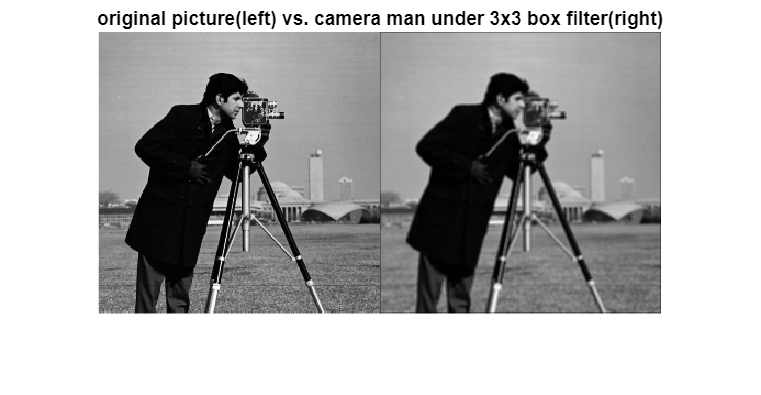

% Q1: box filtering test
a = box_filtering(Icameraman, 3, 3);
b = box_filtering(Icameraman, 5, 5);
c = box_filtering(Icameraman, 9, 9);
figure
imshowpair(Icameraman,a, "montage"), title("original picture(left) vs. camera man under 3x3 box filter(right)");

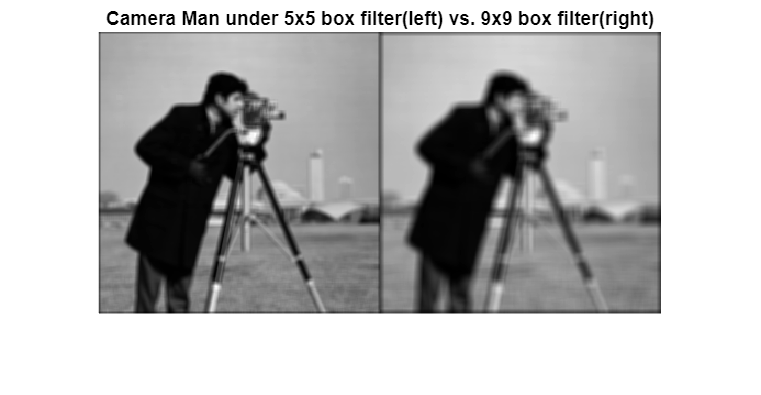

figure
imshowpair(b,c,"montage"), title("Camera Man under 5x5 box filter(left) vs. 9x9 box filter(right)");

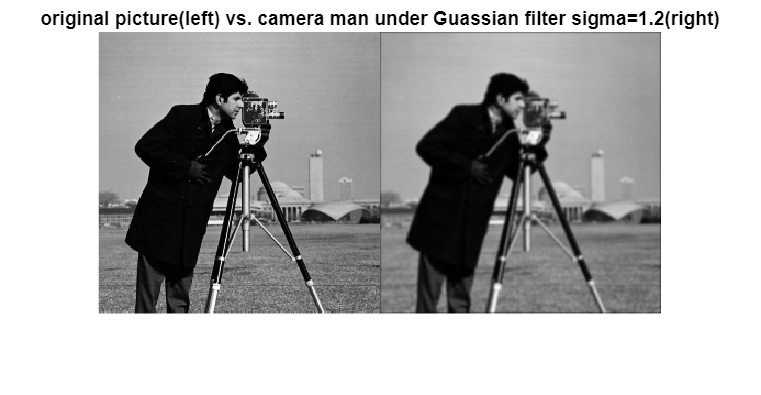

% Q2: Guassian filtering test
sigma=1;

d = gua_filtering(Icameraman,sigma);
e = gua_filtering(Icameraman,3);
f = gua_filtering(Icameraman,5);
figure
imshowpair(Icameraman,d, "montage"), title("original picture(left) vs. camera man under Guassian filter sigma=1.2(right)");

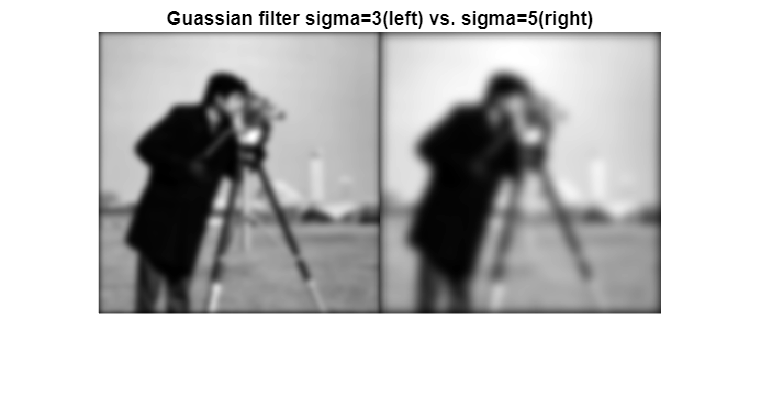

figure
imshowpair(e, f, "montage"), title("Guassian filter sigma=3(left) vs. sigma=5(right)");

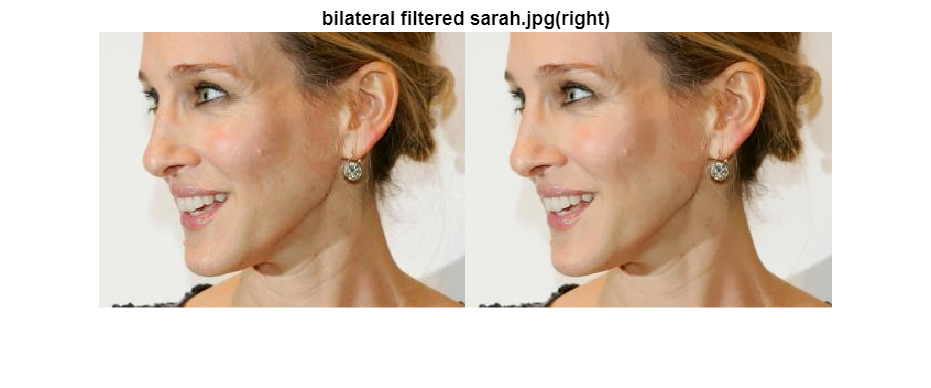

% Q3: Bilateral filtering test
g = bilat_filtering(Isarah, 5, 5);
figure
imshowpair(uint8(Isarah), uint8(g), "montage"), title("bilateral filtered sarah.jpg(right)");

**1. Box filtering (2pts)**

Apply a 3 x 3 box filter to the camera man image. Visualize the result. You can change the box filter size to compare the results.

% box_filtering() function input: 
% Image (double) : an image to apply filter to
% Size_x (double): num of filter cols
% Size_u (double): num of filter rows

% return: boxF (uint8) = filtered image

function boxF=box_filtering(Image, Size_x, Size_y)
    tmp = Size_x*Size_y;                        % calculate num of boxes
    boxMatrix=ones(Size_x, Size_y)/tmp;         % create box filter with same weight at each pixel
    tmp1Matrix=imfilter(Image, boxMatrix);      % apply filter to image, zero-padding by default
    
    boxF=uint8(tmp1Matrix);                     % set return value = filterd image
end

**2. Gaussian filtering (2pts)**Apply a Gaussian filter with sigma=1.2 to the camera man image. Visualize the result. You can change the sigma value to compare the results.

% gua_filtering() function input: 
% Image (double) : an image to apply filter to
% Sigma (double) : standard deviation of the Guassian kernel

% return: guaF (uint8) : filtered image
function guaF=gua_filtering(Image, Sigma)
    halfwid=3*Sigma;
    [xx, yy] = meshgrid(-halfwid:halfwid,-halfwid:halfwid);     % create meshgrid

    Gs=exp(-1/(2*Sigma^2) * (xx.^2 +yy.^2)) / (2*pi*Sigma^2);   % calculate Guassian space kernel

    tmp=imfilter(Image, Gs);                                    % apply Guassian kernel to input image, default zero-padding
    guaF=uint8(tmp);                % assign output = filtered image
end

**3. Bilateral filtering (6pts)**

Apply the bilateral filtering to image “sarah.jpg”. Visualize the result. You can change the sigma_spatial and sigma_intensity to compare the results. You are encouraged to try your own images too.

% bilat_filtering() function input: 
% Image (double) : an image to apply filter to 
% Sigma_s (double) : sigma spatial for determining spatial weight
% Sigma_i (double) : sigma intensity for determinging range weight

% return: bilatF (double) : filtered image-currently greyscale
function bilatF = bilat_filtering(Image, Sigma_s, Sigma_i)
    [height, width, channels] = size(Image);
    filtered_I = zeros(size(Image));
    Snorm = 2 * Sigma_s^2;
    Inorm = 2 * Sigma_i^2;

    for i = 1:height
        for j = 1:width
            Ip = Image(i, j, :);            % Find center intensity (RGB values)
            tmp = zeros(1, 1, channels);    % Total filtered value accumulated in each round
            Wp = 0;                         % Total weight for normalization in the end

            halfwid = 3 * max(Sigma_s, Sigma_i); % Half-width of the kernel

            for u = -halfwid:halfwid
                for v = -halfwid:halfwid
                    Qx = i + u;
                    Qy = j + v;
                    if (Qx > 0 && Qx <= height && Qy > 0 && Qy <= width)    % check for neighbor validity
                        Iq = Image(Qx, Qy, :);

                        Gs = exp(-(u^2 + v^2) / Snorm);
                        Gi = exp(-sum((Ip - Iq).^2) / Inorm); % compute intensity difference for RGB

                        Wcurrent = Gs * Gi;                   % calculate weight at current pixel
                        tmp = tmp + Wcurrent * Iq;
                        Wp = Wp + Wcurrent;                   % update total weight
                    end
                end
            end
            filtered_I(i, j, :) = tmp / Wp;      % final filtered value after normalization
        end
    end

    % output retains double for now
    bilatF = filtered_I;
end
